f = @(x) 1 + x + x.^4

f = function_handle with value:
    @(x)1+x+x.^4


y = 15;

%hC = valor de h / dxC = derivada / eC = error
%Derivada centrada (f(x + hIter) - 2*f(x) + f(x - hIter))/(hIter)
[hC, dxC, eC] = FD4Center(f,y)

hC =     1.0000    0.1000    0.0100    0.0010    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000


dxC = 1.3501e+04

eC = 	1.0e+-5 *

    0.1784    0.1784    0.1784    0.1784    0.1784    0.1784    0.1784    0.1784    0.1784    0.1784


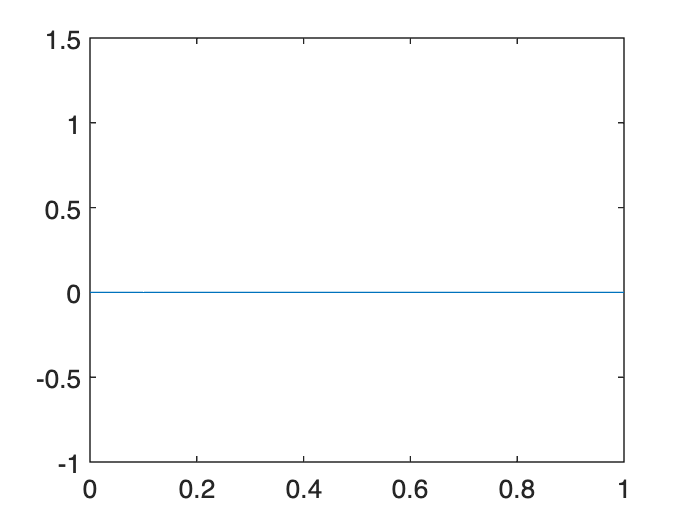

plot(hC, eC)


%Derivada centrada adelantada (f(x + 2*hIter) - 2*f(x + hIter) + f(x))/(hIter)
[hCF, dxCF, eCF] = FD4Forward(f,y)

hCF =     1.0000    0.1000    0.0100    0.0010    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000


dxCF = 1.3501e+04

eCF = 	1.0e+-5 *

    0.3581    0.3581    0.3581    0.3581    0.3581    0.3581    0.3581    0.3581    0.3581    0.3581


plot(hCF, eCF)


%Derivada centrada atrasada (f(x) - 2*f(x - hIter) + f(x - 2*hIter))/(hIter)
[hCB, dxCB, eCB] = FD4Backward(f,y)

hCB =     1.0000    0.1000    0.0100    0.0010    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000


dxCB = 1.3501e+04

eCB = 	1.0e+-6 *

    0.4370    0.4370    0.4370    0.4370    0.4370    0.4370    0.4370    0.4370    0.4370    0.4370


plot(hCB, eCB)

function [h, dx, e] = FD4Center(f, x)
    faux = sym(f);
    df = matlabFunction(diff(faux));
    dxSymT = df(x);
    
    hIter = 1; %start with h = 1
    n = 10;
    lap = 0;
    dx = [];
    e = [];
    h = [];
    xtemp = [];
    dxSym =[];

    while lap < n
        dxSym = [dxSym, dxSymT];
        xtemp = [xtemp, x];
        h = [h, hIter];
        lap = lap + 1;
        hIter = hIter/10;
    end
    
    dx = (-f(x + 2*hIter) + 8*f(x + hIter) - 8*f(x - hIter) + f(x - 2*hIter))/(12*hIter);
    e = abs((dxSym - dx)./dxSym);
end

function [h, dx, e] = FD4Forward(f, x)
    faux = sym(f);
    df = matlabFunction(diff(faux));
    dxSymT = df(x);
    
    hIter = 1; %start with h = 1
    n = 10;
    lap = 0;
    dx = [];
    e = [];
    h = [];
    xtemp = [];
    dxSym =[];

    while lap < n
        dxSym = [dxSym, dxSymT];
        xtemp = [xtemp, x];
        h = [h, hIter];
        lap = lap + 1;
        hIter = hIter/10;
    end
    
    dx = (-f(x + 3*hIter) + 8*f(x + 2*hIter) - 8*f(x) + f(x - hIter))/(12*hIter);
    e = abs((dxSym - dx)./dxSym);
end

function [h, dx, e] = FD4Backward(f, x)
    faux = sym(f);
    df = matlabFunction(diff(faux));
    dxSymT = df(x);
    
    hIter = 1; %start with h = 1
    n = 10;
    lap = 0;
    dx = [];
    e = [];
    h = [];
    xtemp = [];
    dxSym =[];

    while lap < n
        dxSym = [dxSym, dxSymT];
        xtemp = [xtemp, x];
        h = [h, hIter];
        lap = lap + 1;
        hIter = hIter/10;
    end
    
    dx = (-f(x + hIter) + 8*f(x) - 8*f(x - 2*hIter) + f(x - 3*hIter))/(12*hIter);
    e = abs((dxSym - dx)./dxSym);
end

